%1 Problem statement
 % On the basis of the mobile Specification like Battery power, 3G enabled , wifi ,Bluetooth, Ram etc we are predicting Price range of the mobile
%2 Training data_set link ==> https://www.kaggle.com/vikramb/mobile-price-prediction/data?select=train.csv

%3 Drive Link ==> https://drive.google.com/drive/folders/1S0G2f-CqLZu6FQnuGFXyoUCm-M7eSFIk?usp=sharing

%% Clear and Close Figures
clear ; close all; clc

%% Load Data
data =readmatrix('train.csv'); % read comma separated data
%training dataset
X = data(1:1500,1:20); 
y = data(1:1500, 21);


% Scale features and set them to zero mean
[X ,mu ,sigma] = featureNormalize(X);

mu = 	1.0e+03 *

    1.2409    0.0005    0.0015    0.0005    0.0043    0.0005    0.0326    0.0005    0.1410    0.0045    0.0099    0.6493    1.2491    2.1276    0.0123    0.0058    0.0111    0.0008    0.0005    0.0005


sigma = 	1.0e+03 *

    0.4393    0.0005    0.0008    0.0005    0.0044    0.0005    0.0182    0.0003    0.0352    0.0023    0.0061    0.4439    0.4288    1.0972    0.0042    0.0043    0.0054    0.0004    0.0005    0.0005


fprintf('First 10 examples from the dataset: \n');

First 10 examples from the dataset: 


fprintf(' x = [%.0f %.0f], y = %.0f \n', [X(1:10,:) y(1:10,:)]');

 x = [-1 -1], y = 1 
 x = [-1 -1], y = -1 
 x = [-1 0], y = 1 
 x = [-1 -1], y = -1 
 x = [-1 0], y = -1 
 x = [0 1], y = -2 
 x = [-1 1], y = 1 
 x = [-1 1], y = -1 
 x = [1 -1], y = 1 
 x = [1 1], y = -0 
 x = [-1 -1], y = 1 
 x = [2 0], y = 1 
 x = [-1 -1], y = 1 
 x = [1 -1], y = 2 
 x = [-2 1], y = -1 
 x = [1 -1], y = 1 
 x = [0 1], y = 0 
 x = [0 -1], y = 1 
 x = [1 0], y = -0 
 x = [-1 -0], y = 1 
 x = [1 -1], y = 2 
 x = [-1 1], y = 1 
 x = [-1 -1], y = -1 
 x = [-1 1], y = -0 
 x = [1 -0], y = 1 
 x = [1 1], y = 1 
 x = [1 -0], y = 1 
 x = [-1 -1], y = 2 
 x = [1 1], y = -0 
 x = [-1 2], y = 1 
 x = [1 0], y = 0 
 x = [-1 1], y = 1 
 x = [-0 -1], y = -1 
 x = [-1 1], y = 1 
 x = [1 -1], y = 1 
 x = [1 -1], y = -1 
 x = [1 -0], y = -1 
 x = [-1 1], y = 1 
 x = [-2 -0], y = 1 
 x = [1 -1], y = 1 
 x = [-1 -0], y = 1 
 x = [-1 -1], y = 1 
 x = [1 -1], y = 0 
 x = [-1 -0], y = 1 
 x = [-1 1], y = -0 
 x = [2 0], y = -1 
 x = [-1 1], y = 0 
 x = [1 1], y = 1 
 x = [-1 1], y = 3 
 


%  Setup the data matrix appropriately
[m, n] = size(X);

% Add intercept term to X
X = [ones(m, 1) X];
% Initialize the fitting parameters
initial_theta = zeros(length(X(1,:)), 1);
% Set regularization parameter lambda
lambda = 100;


%  Set options for fminunc
disp('using fminunc-->')

using fminunc-->


options = optimoptions(@fminunc,'Algorithm','Quasi-Newton','GradObj', 'on', 'MaxIter', 1000);
% Optimize
[theta, J, exit_flag] = fminunc(@(t)(costFunctionReg(t, X, y, lambda)), initial_theta, options);


Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


% Print theta
fprintf('Cost at theta found by fminunc: %f\n', J);

Cost at theta found by fminunc: 0.086482


disp('theta');disp(theta);

theta
    1.5047
    0.2050
    0.0014
   -0.0104
   -0.0048
    0.0044
   -0.0031
    0.0129
   -0.0054
   -0.0281
    0.0007
    0.0028
    0.1183
    0.1141
    0.9704
    0.0036
   -0.0010
    0.0001
    0.0173
   -0.0058
   -0.0049



% running for training data
testData = readmatrix('train.csv');
t2 = testData(:,1:20);

priceArr = zeros(1500,1);
for i = 1:1:1500
priceArr(i) = [1 (t2(i,1)-mu(1))/sigma(1) (t2(i,2)-mu(2))/sigma(2) (t2(i,3)-mu(3))/sigma(3) (t2(i,4)-mu(4))/sigma(4) (t2(i,5)-mu(5))/sigma(5) (t2(i,6)-mu(6))/sigma(6) (t2(i,7)-mu(7))/sigma(7) (t2(i,8)-mu(8))/sigma(8) (t2(i,9)-mu(9))/sigma(9) (t2(i,10)-mu(10))/sigma(10) (t2(i,11)-mu(11))/sigma(11) (t2(i,12)-mu(12))/sigma(12) (t2(i,13)-mu(13))/sigma(13) (t2(i,14)-mu(14))/sigma(14) (t2(i,15)-mu(15))/sigma(15) (t2(i,16)-mu(16))/sigma(16) (t2(i,17)-mu(17))/sigma(17) (t2(i,18)-mu(18))/sigma(18) (t2(i,19)-mu(19))/sigma(19) (t2(i,20)-mu(20))/sigma(20) ]*theta;    
end
disp("training Accuracy percentage");

training Accuracy percentage


acc = mean(double(int64(priceArr) == y))*100;
disp(acc);

   86.7333



% running for CV data
X_CV = data(1501:1800,1:20);
y_CV = data(1501:1800,21);
t2 = X_CV(:,1:20);
priceArr2 = zeros(300,1);
for i = 1:1:300
priceArr2(i) = [1 (t2(i,1)-mu(1))/sigma(1) (t2(i,2)-mu(2))/sigma(2) (t2(i,3)-mu(3))/sigma(3) (t2(i,4)-mu(4))/sigma(4) (t2(i,5)-mu(5))/sigma(5) (t2(i,6)-mu(6))/sigma(6) (t2(i,7)-mu(7))/sigma(7) (t2(i,8)-mu(8))/sigma(8) (t2(i,9)-mu(9))/sigma(9) (t2(i,10)-mu(10))/sigma(10) (t2(i,11)-mu(11))/sigma(11) (t2(i,12)-mu(12))/sigma(12) (t2(i,13)-mu(13))/sigma(13) (t2(i,14)-mu(14))/sigma(14) (t2(i,15)-mu(15))/sigma(15) (t2(i,16)-mu(16))/sigma(16) (t2(i,17)-mu(17))/sigma(17) (t2(i,18)-mu(18))/sigma(18) (t2(i,19)-mu(19))/sigma(19) (t2(i,20)-mu(20))/sigma(20) ]*theta;    
end

disp("Predicted price for test data")

Predicted price for test data


acc = mean(double(int64(priceArr2) == y_CV))*100;
disp(acc);

   86.6667



% running for test data
X_test = data(1801:2000,1:20);
y_test = data(1801:2000,21);

t2 = X_test(:,1:20);
priceArr3 = zeros(200,1);
for i = 1:1:200
priceArr3(i) = [1 (t2(i,1)-mu(1))/sigma(1) (t2(i,2)-mu(2))/sigma(2) (t2(i,3)-mu(3))/sigma(3) (t2(i,4)-mu(4))/sigma(4) (t2(i,5)-mu(5))/sigma(5) (t2(i,6)-mu(6))/sigma(6) (t2(i,7)-mu(7))/sigma(7) (t2(i,8)-mu(8))/sigma(8) (t2(i,9)-mu(9))/sigma(9) (t2(i,10)-mu(10))/sigma(10) (t2(i,11)-mu(11))/sigma(11) (t2(i,12)-mu(12))/sigma(12) (t2(i,13)-mu(13))/sigma(13) (t2(i,14)-mu(14))/sigma(14) (t2(i,15)-mu(15))/sigma(15) (t2(i,16)-mu(16))/sigma(16) (t2(i,17)-mu(17))/sigma(17) (t2(i,18)-mu(18))/sigma(18) (t2(i,19)-mu(19))/sigma(19) (t2(i,20)-mu(20))/sigma(20) ]*theta;    
end

disp("Predicted price for test data")

Predicted price for test data


acc = mean(double(int64(priceArr3) == y_test))*100;
disp(acc);

    87



train_cost = computeCostMulti(X,y,theta);
disp(train_cost);

    0.0527



% corss validation cost
m_CV = length(y_CV);
[X_CV ,~ ,~] = featureNormalize(X_CV);

mu = 	1.0e+03 *

    1.2470    0.0005    0.0015    0.0005    0.0046    0.0006    0.0306    0.0005    0.1379    0.0046    0.0100    0.6385    1.2774    2.1760    0.0125    0.0060    0.0111    0.0008    0.0005    0.0005


sigma = 	1.0e+03 *

    0.4348    0.0005    0.0008    0.0005    0.0045    0.0005    0.0176    0.0003    0.0361    0.0023    0.0061    0.4617    0.4414    1.0288    0.0042    0.0045    0.0056    0.0004    0.0005    0.0005



X_CV = [ones(m_CV, 1) X_CV];

CV_cost = computeCostMulti(X_CV,y_CV,theta);
disp(CV_cost);

    0.0562




% test cost
m_test = length(y_test);
[X_test ,~ ,~] = featureNormalize(X_test);

mu = 	1.0e+03 *

    1.2076    0.0005    0.0015    0.0005    0.0040    0.0005    0.0303    0.0005    0.1383    0.0046    0.0101    0.6235    1.2310    2.0208    0.0117    0.0054    0.0101    0.0008    0.0005    0.0005


sigma = 	1.0e+03 *

    0.4480    0.0005    0.0008    0.0005    0.0040    0.0005    0.0187    0.0003    0.0357    0.0022    0.0060    0.4157    0.4444    1.0708    0.0042    0.0043    0.0057    0.0004    0.0005    0.0005


X_test = [ones(m_test, 1) X_test];
test_cost = computeCostMulti(X_test,y_test,theta);
disp(test_cost);

    0.0647



r = Rsq(X,y,theta);
disp("R squared value ");

R squared value 


disp(r);

    0.9160



[All_lambda, error_train, error_CV] = validationCurve(X, y, X_CV, y_CV);


Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>

Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<

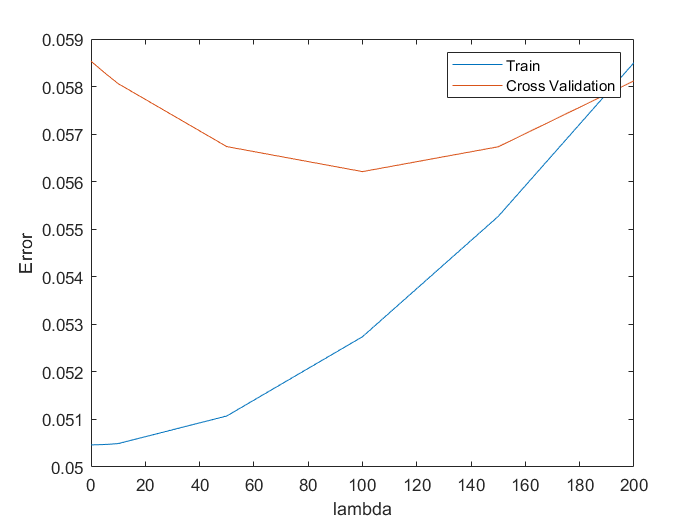

plot(All_lambda, error_train, All_lambda, error_CV);
legend('Train', 'Cross Validation');
xlabel('lambda');
ylabel('Error');

for i = 1:length(All_lambda)
    if i == 1
        fprintf('lambda\t\tTrain Error\tValidation Error\n');
    end
   
    fprintf('%f\t%f\t%f\n',All_lambda(i), error_train(i), error_CV(i));
end

lambda		Train Error	Validation Error


0.000100	0.050466	0.058535
0.000500	0.050466	0.058535
0.001000	0.050466	0.058535
0.005000	0.050466	0.058535
0.010000	0.050466	0.058534
0.050000	0.050466	0.058532
0.100000	0.050466	0.058530
0.500000	0.050466	0.058510
0.000000	0.050466	0.058535
1.000000	0.050466	0.058485
5.000000	0.050473	0.058291
10.000000	0.050492	0.058061
50.000000	0.051073	0.056738
100.000000	0.052740	0.056212
150.000000	0.055271	0.056734
200.000000	0.058503	0.058120


disp("optimal Lambda"), disp(100);

optimal Lambda
   100



fprintf('minimum train cost => %f\t minimum cross validation cost => %f\t\n',min(error_train),min(error_CV));

minimum train cost => 0.050466	 minimum cross validation cost => 0.056212	
